%Identificacion Friccion
%[pks,locs] = findpeaks(Angle,Time)

f=fit(locs,pks,"exp1")

f =      General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       83.17  (77.5, 88.85)
       b =       -0.29  (-0.3209, -0.259)

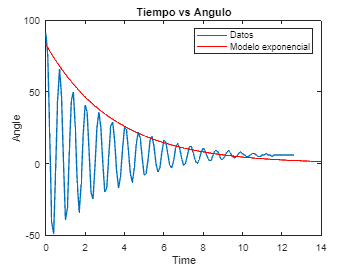


plot(Time,Angle)
hold on
plot(f)
hold off
legend("Datos","Modelo exponencial")
title("Tiempo vs Angulo")
xlabel("Time")
ylabel("Angle")

%Identificación de k para motor vs voltaje-motor
p = polyfit(PWM,Angle2,1)

p =     0.9605   -2.3305


a = p(1)

a = 0.9605

b = p(2)

b = -2.3305

yfit = polyval(p,PWM)

yfit =    74.5124
   74.5124
   74.5124
   74.5124
   74.5124
   73.5518
   73.5518
   73.5518
   73.5518
   73.5518


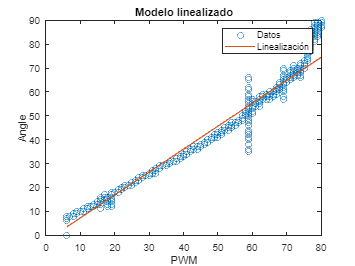


plot(PWM,Angle2,"o",PWM,yfit)
legend("Datos","Linealización")
title("Modelo linealizado")
xlabel("PWM")
ylabel("Angle")

%Función de transferencia
k = 0.9605

k = 0.9605

mb = 12/1000

mb = 0.0120

mm = 3.5/1000

mm = 0.0035

dm = 12.6/100

dm = 0.1260

db = 5.5/100

db = 0.0550

g = 9.8

g = 9.8000

I = 1.2e-4

I = 1.2000e-04

gamma = 0.29

gamma = 0.2900

beta = gamma * 2 * I

beta = 6.9600e-05

theta = 55

theta = 55


num = [0 (k*dm/I)]

num = 1.0e+03 *

         0    1.0085


den = [1 (beta/I) (g*(mm*dm+mb*db)/I)*cosd(55)]

den =     1.0000    0.5800   51.5731



G = tf(num,den)

G =
 
          1009
  --------------------
  s^2 + 0.58 s + 51.57
 
Continuous-time transfer function.
Model Properties


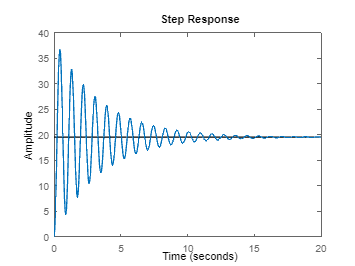


step(G)

figure
hold on
step(G)
plot(Time,Angle,"-g")
legend("G","Datos","e")

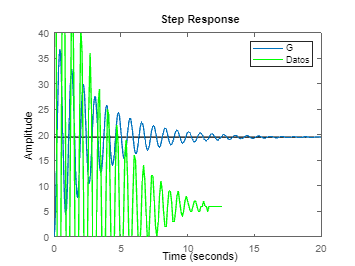

hold off